# Load Matlab datafile

clear all;
%load(fullfile('ECG.mat'));
load(fullfile('PPGDATAN.mat'));
%load(fullfile('NewPPGData.mat'));
%load(fullfile('ECGNEW2.mat'));
%load(fullfile('ECGNEW.mat'));
%load(fullfile('PPG.mat'));
%load(fullfile('GSR.mat'));
%load(fullfile('ECGPPG.mat'));
%load(fullfile('ECGGSR.mat'));
%Data = importdata('TT2.csv');
%Data = importdata('ECGACC.csv');
%TrainTestData = Data.Data;
%train_n_test_label = Data.Labels;
TrainTestData = PPGDATA.data;
train_n_test_label = PPGDATA.label;

%TrainTestData = newPPGTest.Data;
%train_n_test_label = newPPGTest.Labels;
%TrainTestData = ECGData.Data;
%train_n_test_label = ECGData.Labels;
%TrainTestData=[TrainD(2:end),TestD(2:end)]
%train_n_test_label=[TrainD(1:), TestD(1:)]
%TrainTestData=TrainTestData(1:53,1:60000);
%newTrainTestData = squeeze(mean(reshape(TrainTestData,[5,53,12000]),1));
%newTrainTestData=smoothdata(newTrainTestData,'sgolay');

## Split data into testing and training set

%trainData1 = TrainTestData(:,1:45000);
%testData1 = TrainTestData(:,45001:65536);
%trainData1 = TrainTestData(:,1:8000);
%testData1 = TrainTestData(:,8001:16000);

%%trainData1 = TrainTestData(:,1:30000);
%testData1 = TrainTestData(:,30001:60000);
%trainData1 = TrainTestData(:,1:16000);
%testData1 = TrainTestData(:,16001:32000);

%trainData1 = TrainTestData(:,16001:32000);
%testData1 = TrainTestData(:,32001:48000);

DataSegment1 = TrainTestData(:,1:8000);
DataSegment2 = TrainTestData(:,8001:16000);
DataSegment3 = TrainTestData(:,16001:24000);
DataSegment4 = TrainTestData(:,24001:32000);
DataSegment5 = TrainTestData(:,32001:40000);
DataSegment6 = TrainTestData(:,40001:48000);
DataSegment7 = TrainTestData(:,48001:56000);
%FinalDataSegment=DataSegment1+DataSegment3+DataSegment4+DataSegment5+DataSegment6+DataSegment7;  
FinalDataSegment=vertcat(DataSegment1(1:53,:),DataSegment2(1:53,:),DataSegment3(1:53,:),DataSegment4(1:53,:),DataSegment5(1:53,:),DataSegment6(1:53,:),DataSegment7(1:53,:));
%FinalDataSegment=vertcat(DataSegment1(1:9,:),DataSegment2(1:9,:),DataSegment3(1:9,:));
%newDataSegment1=TrainTestData2(:,1:8000);
%newDataSegment2=TrainTestData2(:,8001:16000);
%newDataSegment3=TrainTestData2(:,16001:24000);
%train_n_test_label=vertcat(train_n_test_label(:),train_n_test_label(:),train_n_test_label(:));
train_n_test_label=vertcat(train_n_test_label(:),train_n_test_label(:),train_n_test_label(:),train_n_test_label(:),train_n_test_label(:),train_n_test_label(:),train_n_test_label(:));
%newDataSegment=newDataSegment1+newDataSegment2+newDataSegment3;  

TrainData1 = FinalDataSegment(:,1:4000);
%TrainData2 = newDataSegment(:,1:2000);
%TrainDataFinal=[ceil(TrainData1);ceil(TrainData2/1000)];
TestData1=FinalDataSegment(:,4001:8000);
%TestData1=ceil(FinalDataSegment(:,2001:4000));
%TestData2=TrainTestData2(:,2001:4000);
%TestDataFinal = [TestData1;ceil(TestData2/1000)];


## Feature extraction

%timeWindow = 8192;
%timeWindow = 1600; % for ECGPPG, GSR
%timeWindow = 8192; % for ECGPPG, GSR
timeWindow = 4000; %For other signals
%timeWindow = 800; %For other signals
%timeWindow = 1000;
AROrder = 8;

transformLevel = 2;
%transformLevel = 5;
%[trainFeatures,testFeatures,featureindices] = featureExtraction(trainData,testData,timeWindow,AROrder,transformLevel);
[trainFeatures,featureindices] = featureExtraction(TrainData1,timeWindow,AROrder,transformLevel);
%{
[trainFeatures1,featureindices] = featureExtraction(DataSegment2,timeWindow,AROrder,transformLevel);
[trainFeatures2,featureindices] = featureExtraction(DataSegment3,timeWindow,AROrder,transformLevel);
[trainFeatures3,featureindices] = featureExtraction(DataSegment4,timeWindow,AROrder,transformLevel);
[trainFeatures4,featureindices] = featureExtraction(DataSegment5,timeWindow,AROrder,transformLevel);
%}
[testFeatures,featureindices] = featureExtraction(TestData1,timeWindow,AROrder,transformLevel);
%[testFeatures2,featureindices] = featureExtraction2(DataSegment7,timeWindow,AROrder,transformLevel);

%[trainFeaturesFinal]=trainFeatures+trainFeatures1+trainFeatures2+trainFeatures3+trainFeatures4;
%fs=125;
%trainFeatures=mat2cell(trainFeatures,[]);   
%pentropyTrain = cellfun(@(x)pentropy(x,fs)',trainFeatures,'UniformOutput',false);
%[testFeaturesFinal]=testFeatures+testFeatures2;
%testFeatures=mat2cell(testFeatures);
%pentropyTest = cellfun(@(x)pentropy(x,fs)',testFeatures,'UniformOutput',false);

allFeatures = [trainFeatures;testFeatures];
allLabels = [train_n_test_label;train_n_test_label];

%allLabels = [train_n_test_labelCopy;train_n_test_labelCopy];
%{
figure
boxplot(allFeatures(:,featureindices.SEfeatures(1)),allLabels,'notch','on')
boxplot(allFeatures(:,featureindices.SEfeatures(2)),allLabels,'notch','on')
plot(allFeatures(:,featureindices.SEfeatures(1)))
ylabel('Entropy')
title('Feature Extraction')

plot(allFeatures(:,featureindices.ARfeatures(1)))
ylabel('AR Coefficient')
title('Feature Extraction')
figure
boxplot(allFeatures(:,featureindices.ARfeatures(1)),allLabels,'notch','on')
ylabel('Holder Exponent Range')
title('Range of Singularity Spectrum by Group (First Time Window)')
grid on

%plot(allFeatures(:,featureindices.varianceFeatures(1)))
%ylabel('Wavelet Variance')
%title('Feature Extraction for PPG')
%boxplot(allFeatures(:,featureindices.varianceFeatures(end-1)),allLabels,'notch','on')
%ylabel('Wavelet Variance')
%title('Wavelet Variance by Group')
%grid on

%features = [trainFeatures; testFeatures];
%}

## Feature Selection

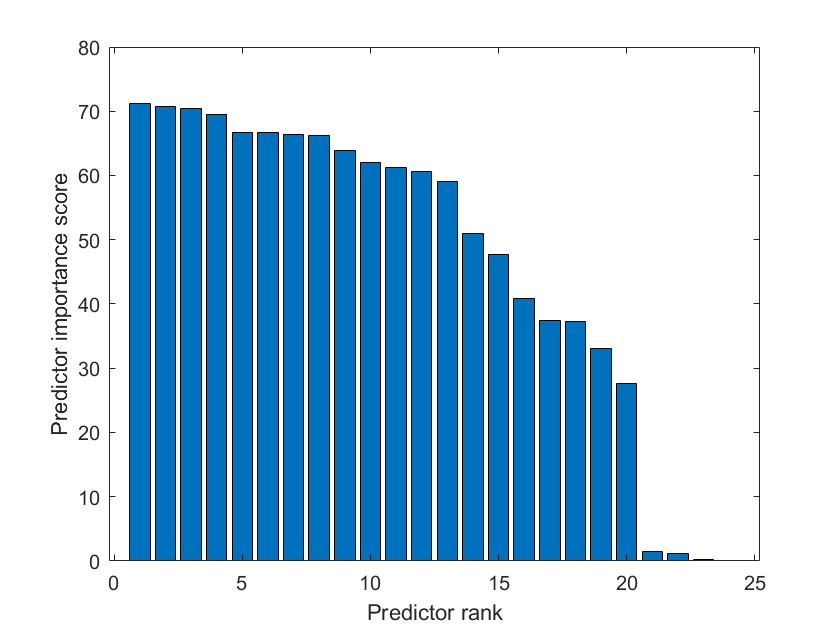

%Feature Selection
   [idx,scores] = fscchi2(trainFeatures,train_n_test_label);
   %[idx,scores] = fscmrmr(trainFeatures,train_n_test_label);
   %[idx,scores] = relieff(trainFeatures,train_n_test_label,12);
    % Select features with weight above 1
   % selected_feature_indx = find(mdl.FeatureWeights > 0.5);
    % Select 50 important features

    bar(scores(idx))
    %idx=sort(idx);
    xlabel('Predictor rank')
    ylabel('Predictor importance score')

    
    %selected_feature_indx =  idx(:,1:6);%85.5% with haar took 6 features out of 11
    %selected_feature_indx =  idx(:,1:5);%82.3% with db15/db10 6 features out of 11
    %selected_feature_indx =  idx(:,1:8); %85.5% with coffi, n=1
    %selected_feature_indx =  idx(:,1:7); %82.3% with coffi, n=2
    %selected_feature_indx =  idx(:,1:6); %82.3% with coffi, n=3
    %selected_feature_indx =  idx(:,1:6);%83.9% with fk, co=14, features =5
    %selected_feature_indx =  idx(:,1:7);%85.5% with sym2, features =7 outof 9
    
    %selected_feature_indx =  idx(:,1:6); %88.47 Ea Ed sigenergy' wp
    
    %selected_feature_indx =  idx(:,1:2); % 88.7 Ed sigenergy'
    selected_feature_indx =  idx(:,1:12); %85 good
    %selected_feature_indx =  idx(:,find(scores>=5))
  
   % selected_feature_indx =  idx(:,1:20);%wvar + se  92.5%.
    %selected_feature_indx =  idx(:,1:45);%wvar + se +2fq 88.7%., f1:93%, recall 1, precisson 0.8696
    %selected_feature_indx =  idx(:,1:42);;%wvar + se +wentropy %without ranking 90.6%
    %selected_feature_indx =  idx(:,find(scores>=0.9));%wvar + se +wentropy %wit ranking 90.6%
    %selected_feature_indx=  idx(:,1:20);
    %selected_feature_indx = idx(:,find(scores>=5));%wvar + se +wentropy %wit ranking 90.6%
    %selected_feature_indx =  idx(:,1:45);
    % Plot feature weights
    %stem(mdl.FeatureWeights,'bo');
    bar(scores(idx))
    xlabel('Predictor rank')
    ylabel('Predictor importance score')

    
    % save for future reference
    save('SelectedFeatures', 'selected_feature_indx');

## classification

rng(1)
%modelKNN = fitcknn(trainFeatures,train_n_test_label);
%modelKNN=fitcensemble(trainFeatures,train_n_test_label)
%t = templateNaiveBayes('DistributionNames','kernel')
%Mdl = fitcecoc(trainFeatures,train_n_test_label,'Learners',t);
classNames = {'AUTH','NAUTH'}; % Class order
prior = [0.75 0.25];
%{
modelKNN = fitcnb(trainFeatures(:,selected_feature_indx),train_n_test_label,...
       'ClassNames',{'AUTH','NAUTH'},'Prior',prior)
%}

modelKNN = fitcknn(trainFeatures(:,selected_feature_indx),train_n_test_label);

%modelKNN = fitcgam(trainFeatures(:,selected_feature_indx),train_n_test_label);
%modelKNN = fitcensemble(trainFeatures(:,selected_feature_indx),train_n_test_label);
%modelKNN = fitcgam(trainFeatures,train_n_test_label);
%modelKNN = fitcecoc(trainFeatures,train_n_test_label);
%{
    % modelKNN = fitcknn(trainFeatures1,train_n_test_label);
modelKNN = fitcknn(trainFeatures2,train_n_test_label);
modelKNN = fitcknn(trainFeatures3,train_n_test_label);
modelKNN = fitcknn(trainFeatures4,train_n_test_label);
%modelEN = fitcensemble(trainFeatures,train_n_test_label);
%}

%modelNV = fitcnb(trainFeatures,train_n_test_label,'ClassNames',classNames,'Prior',prior)
%{
modelNV = fitcnb(X,Y,'ClassNames',classNames,'OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
    'expected-improvement-plus'))
defaultPriorMdl = modelNV;
FreqDist = cell2table(tabulate(train_n_test_label));
defaultPriorMdl.Prior = FreqDist{:,2};


defaultCVMdl = crossval(defaultPriorMdl);
defaultLoss = kfoldLoss(defaultCVMdl)
rng default
%}

kfoldmodel = crossval(modelKNN,'KFold',10);
classLabels = kfoldPredict(kfoldmodel);
loss = kfoldLoss(kfoldmodel)

loss = 0.1348

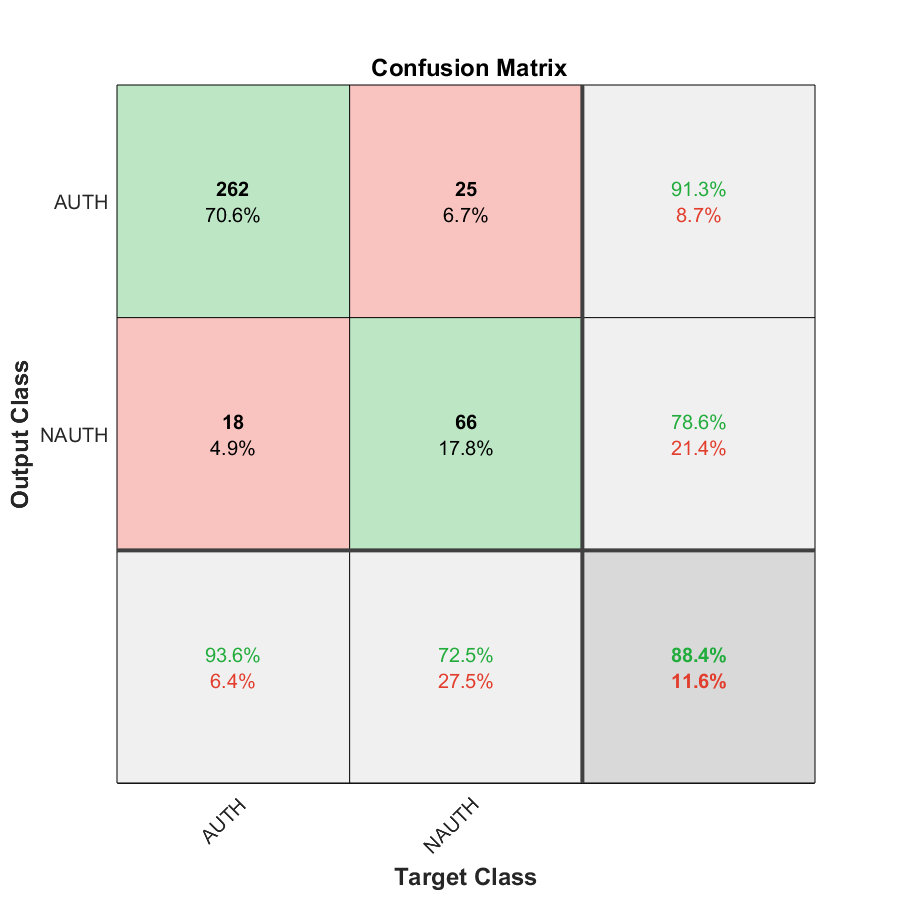

%CVMdl = crossval(modelNV);
%Loss = kfoldLoss(CVMdl)

%isLabels1 = resubPredict(modelNV);
%confusionMatrix = confusionchart(train_n_test_label,isLabels1);
%plotconfusion(categorical(train_n_test_label),categorical(isLabels1));

%predLabels = predict(modelEN,testFeatures);
predLabels = predict(modelKNN,testFeatures(:,selected_feature_indx));
%predLabels = predict(modelKNN,testFeatures2);
%[label,score]=predict(modelKNN,testFeatures);
%classOrder = modelKNN.ClassNames
%correctPredictions = strcmp(predLabels,testLabel);
correctPredictions = strcmp(predLabels,train_n_test_label);
[confusionMatrix] = confusionmat(train_n_test_label,predLabels);
plotconfusion(categorical(train_n_test_label),categorical(predLabels));

%mdlSVM = fitcsvm(testFeatures,predLabels,'Standardize',true);
%mdlSVM = fitPosterior(mdlSVM);


## calculate prediction results

truePositive = confusionMatrix(1,1);
falsePositive = sum(confusionMatrix(:,1)) - confusionMatrix(1,1);
falseNegative = sum(confusionMatrix(1,:)) - confusionMatrix(1,1);
trueNegative = confusionMatrix(2,2);

precision = truePositive / (truePositive + falsePositive);
recall = truePositive / (truePositive + falseNegative);
trueNegativeRate = trueNegative / (trueNegative+falsePositive);
falseNegativeRate = falseNegative / (falseNegative+truePositive);
falsePositiveRate= 1 - trueNegativeRate;
truePositiveRate= truePositive/(truePositive + falseNegative);
f1 = 2 * precision * recall / (precision + recall);
EER=(falsePositive+falseNegative) / (truePositive+falsePositive+falsePositive+trueNegative);

## display result

%testAccuracy = sum(correctPredictions) / length(testLabel)*100
%testAccuracy = sum(correctPredictions) / length(train_n_test_label)*100

%confusionMatrixTable = array2table([truePositive falsePositive;...
  %  falseNegative trueNegative],'VariableNames',{'Positive','Negative'},'RowNames',...
   % {'Positive','Negative'});

%resultTable = array2table([precision recall f1 trueNegativeRate ...
   % falseNegativeRate falsePositiveRate],'VariableNames',{'Precision','Recall','F1_Score',...
   % 'True Negative Rate', 'False Negative Rate', 'False Positive Rate' },'RowNames',...
   % {'value',});

%%disp(confusionMatrixTable);
%disp(resultTable);

AUC Curve


%[Xsvm,Ysvm,Tsvm,AUCsvm] = perfcurve(predLabels,score(:,1),'AUTH');
%[Xsvm1,Ysvm2,Tsvm2,AUCsvm2] = perfcurve(predLabels,score(:,2),'NAUTH');
%plot(Xsvm,Ysvm)
%xlabel('False positive rate') 
%ylabel('True positive rate')
%title('ROC for Classification')



